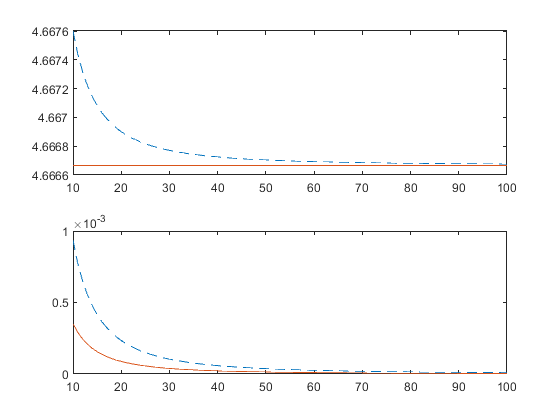

clear; clc;

n = 10:100;
y = ones(1,90);
hor = 14/3*ones(size(n));
err = ones(1,91);
lub = ones(1,91);

for i = n
    dx = 3/i;
    xmid = dx/2:dx:3-dx/2;
    fxmid = sqrt(xmid+1);
    approx = dx*sum(fxmid);
    y(i-9) = approx;
    err(i-9) = abs(14/3-approx);
    lub(i-9) = abs(27*(-1/32)/(24*i^2));
end

subplot(2,1,1)
plot(n,y,'--')
hold on
plot(n,hor)

subplot(2,1,2)
plot(n,err,'--')
hold on
plot(n,lub)